# Diffusion in an Energy Potential

For this example, suppose that the same spherical protein from *example1.mlx* is attached to a spring, and that the spring is anchored at one end ($x_0$ = 0), as shown in the diagram below.

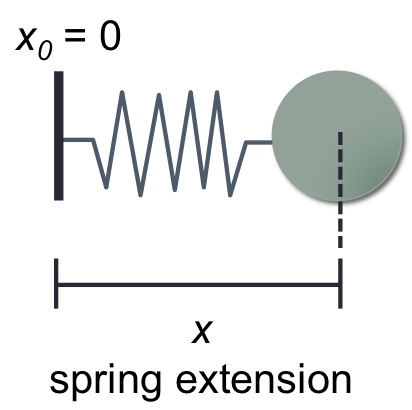

Assuming that the spring constant is 1 pN/nm, let's simulate the diffusive motion of the protein for 1000 steps with a time step of 0.1 microsecond. 

% assign parameter values
MW = 150; %g/mol (Da)
density = 1400; %kg/m^3
nu = 0.005; %kg/m*s
T = 310; %K
kB = 1.381e-23; %J/K, Boltzmann's constant
N_A = 6.022e23; %mol^-1, Avogadro's number
kappa = 1e-3; %N/m, spring constant

dt = 0.1e-6; %s, time step for simulation
Nsteps = 1000; % total number of steps to simulate
Nmolec = 1; %number of molecules to simulate

% solve for other parameters
R = ((3*MW)/(4*density*pi*N_A))^(1/3); %m, spherical radius of a single molecule
D = (kB*T)/(6*pi*nu*R); %m^2/s, diffusion coefficient
dx = sqrt(2*D*dt); %m, diffusive step size in one dimension

% initialize arrays
xpos = zeros(Nsteps,1); % molecule position
time = zeros(Nsteps,1); % time

## Implementation of Boltzmann's law

Boltzmann's law can be used to determine the probability that the tethered protein moves to states of higher energy (i.e. stretching the spring).  Remember, Boltzmann's law gives us

Eq. 2.1                                $\frac{p_2 }{p_1 }=\mathrm{exp}\left(\frac{-\Delta U}{k_B T}\right)$                                                       

and the energy ($U$) of stretching a spring is 

Eq. 2.2                                     $U=\frac{1}{2}\kappa x^2$

For each randomly generated step from $\left\lbrack -\Delta x,\Delta x\right\rbrack$, the probability of movement is given by$p=\mathrm{min}\left\lbrack 1,\mathrm{exp}\left(-\Delta U/k_B T\right)\right\rbrack$.  Note that in the case that the protein moves from a state of high energy to one of low energy ($\Delta U<0$) Eq. 2.1 gives a value greater than 1, such that the protein always moves to states of lower energy.  For instances when $\Delta U>0$, if the random number is less than or equal to $p$ (Eq. 2.1), then the move is allowed.  Otherwise the protein does not move while time is advance.  This simulation approach is referred to as **Metropolis Monte Carlo**, and obeys the equations of diffusive motion when the average energy ($\Delta U$) is small (i.e. less than 1 $k_B T$).  *Note, this is why a smaller time step is used here compared to *example1.mlx*.

% simulate diffusion of the tethered protein in 1-dimension
for i = 2:Nsteps
    temp = rand; %generate a uniformly distributed random number 
    if temp<=0.5 %tries to move to the right
        U1 = (1/2)*kappa*(xpos(i-1))^2; %energy at current position
        U2 = (1/2)*kappa*(xpos(i-1)+dx)^2; %energy at the potential new position
        p = min([1,exp(-(U2-U1)/(kB*T))]); %Boltzmann's law
        temp2 = rand; %generate a second random number to determine if move is executed or not
        if temp2<=p
            xpos(i) = xpos(i-1)+dx; %step to the right
        else
            xpos(i) = xpos(i-1); %stays in the same place
        end
    else %tries to move to the left
        U1 = (1/2)*kappa*(xpos(i-1))^2; %energy at current position
        U2 = (1/2)*kappa*(xpos(i-1)-dx)^2; %energy at the potential new position
        p = min([1,exp(-(U2-U1)/(kB*T))]); %Boltzmann's law 
        temp2 = rand;
        if temp2<=p
            xpos(i) = xpos(i-1)-dx; %step to the left
        else
            xpos(i) = xpos(i-1); %stays in the same place
        end
    end
    time(i)=time(i-1)+dt; % time is advanced regardless of whether or not the protein moves.
end

Let's view the resulting trajectory.

figure(1);clf
plot(time,xpos)
xlabel('time (sec)','FontSize',12)
ylabel('x-position (m)','FontSize',12)

What happens if we soften the spring?

%assign new spring constant
kappa = 0.1e-3;%N/m, spring constant
% simulate diffusion of the tethered protein in 1-dimension
for i = 2:Nsteps
    temp = rand; %generate a uniformly distributed random number 
    if temp<=0.5 %tries to move to the right
        U1 = (1/2)*kappa*(xpos(i-1))^2; %energy at current position
        U2 = (1/2)*kappa*(xpos(i-1)+dx)^2; %energy at the potential new position
        p = min([1,exp(-(U2-U1)/(kB*T))]); %Boltzmann's law
        temp2 = rand; %generate a second random number to determine if move is executed or not
        if temp2<=p
            xpos(i) = xpos(i-1)+dx; %step to the right
        else
            xpos(i) = xpos(i-1); %stays in the same place
        end
    else %tries to move to the left
        U1 = (1/2)*kappa*(xpos(i-1))^2; %energy at current position
        U2 = (1/2)*kappa*(xpos(i-1)-dx)^2; %energy at the potential new position
        p = min([1,exp(-(U2-U1)/(kB*T))]); %Boltzmann's law 
        temp2 = rand;
        if temp2<=p
            xpos(i) = xpos(i-1)-dx; %step to the left
        else
            xpos(i) = xpos(i-1); %stays in the same place
        end
    end
    time(i)=time(i-1)+dt; % time is advanced regardless of whether or not the protein moves.
end
%plot the results on top of the previous run
figure(1);hold on;
plot(time,xpos,'r')
xlabel('time (sec)','FontSize',12)
ylabel('x-position (m)','FontSize',12)

When the spring is softer, the protein is allowed to vary more from rest position because less mechanical force acts upon it at small deviations.

## Equipartition of Energy

The **Principle of Equipartition of Energy** states that if the energy of a particle depends on the square of a parameter (i.e. the extension of a spring in Eq 2.2 above), then the mean energy associated with that degree of freedom is one-half a unit of thermal energy,$\left(1/2\right)k_B T$.  From this Principle, we can obtain 

Eq. 2.3                                    $\frac{1}{2}k_B T=\left\langle U\right\rangle =\frac{1}{2}\kappa \left\langle x^2 \right\rangle$

where $\left\langle x^2 \right\rangle$ is the mean-squared displacement (MSD) of the particle in time or an ensemble of proteins at a single time point.  Therefore, 

Eq. 2.4                                            $\left\langle x^2 \right\rangle =\frac{k_B T}{\kappa }$

Let's check to see if the simulation reproduces the theoretically expected result!  To do so, let's simulate 1000 iterations of the simulation above with the oringal spring constant value of 1 pN/nm, and record the final position of each iteration. 

%re-assign the orignal spring constant value and update the total number of runs to simulate
kappa = 1e-3;%N/m, spring constant
Nmolec = 100;%number of molecules to simulate
%initialize an array to record the final positions of each run
fpos = zeros(Nmolec,1);

for n = 1:Nmolec %loop through the total number of runs
    xpos = zeros(Nsteps,1); %initialize the position array for each run
    % simulate diffusion of the tethered protein in 1-dimension
    for i = 2:Nsteps
        temp = rand; %generate a uniformly distributed random number
        if temp<=0.5 %tries to move to the right
            U1 = (1/2)*kappa*(xpos(i-1))^2; %energy at current position
            U2 = (1/2)*kappa*(xpos(i-1)+dx)^2; %energy at the potential new position
            p = min([1,exp(-(U2-U1)/(kB*T))]); %Boltzmann's law
            temp2 = rand; %generate a second random number to determine if move is executed or not
            if temp2<=p
                xpos(i) = xpos(i-1)+dx; %step to the right
            else
                xpos(i) = xpos(i-1); %stays in the same place
            end
        else %tries to move to the left
            U1 = (1/2)*kappa*(xpos(i-1))^2; %energy at current position
            U2 = (1/2)*kappa*(xpos(i-1)-dx)^2; %energy at the potential new position
            p = min([1,exp(-(U2-U1)/(kB*T))]); %Boltzmann's law
            temp2 = rand;
            if temp2<=p
                xpos(i) = xpos(i-1)-dx; %step to the left
            else
                xpos(i) = xpos(i-1); %stays in the same place
            end
        end
        time(i)=time(i-1)+dt; % time is advanced regardless of whether or not the protein moves.
    end
    fpos(n) = xpos(end); %record the final position of the protein for this run
end
%plot the resulting position distribution
figure(2);clf
hist(fpos,10)

Does the resulting MSD agree with the theoretical value?

% simulated mean-squared displacement
MSD = mean(fpos.^2)
% theoretical
theoMSD = (kB*T)/kappa


Interestingly, this simple model of a tethered spring can be applied to understanding the forces in an **optical trap**.  An optical trap is a tool used in biophysics in which a glass bead is held in the center of a focused laser beam, as shown in the diagram below.  Due to the refractive index of the glass bead, the momentum of photons passing through it changes, and thus a force is imparted on the bead.  The further the bead deviates from the focal point of the laser, the higher the returning force.  Because the bead is very small (~ 1 micrometer in diameter), it is subject to thermal forces.  And as a result, the MSD of the bead can be used to calculate the effective spring constant of the optical trap using Eq. 2.4 above

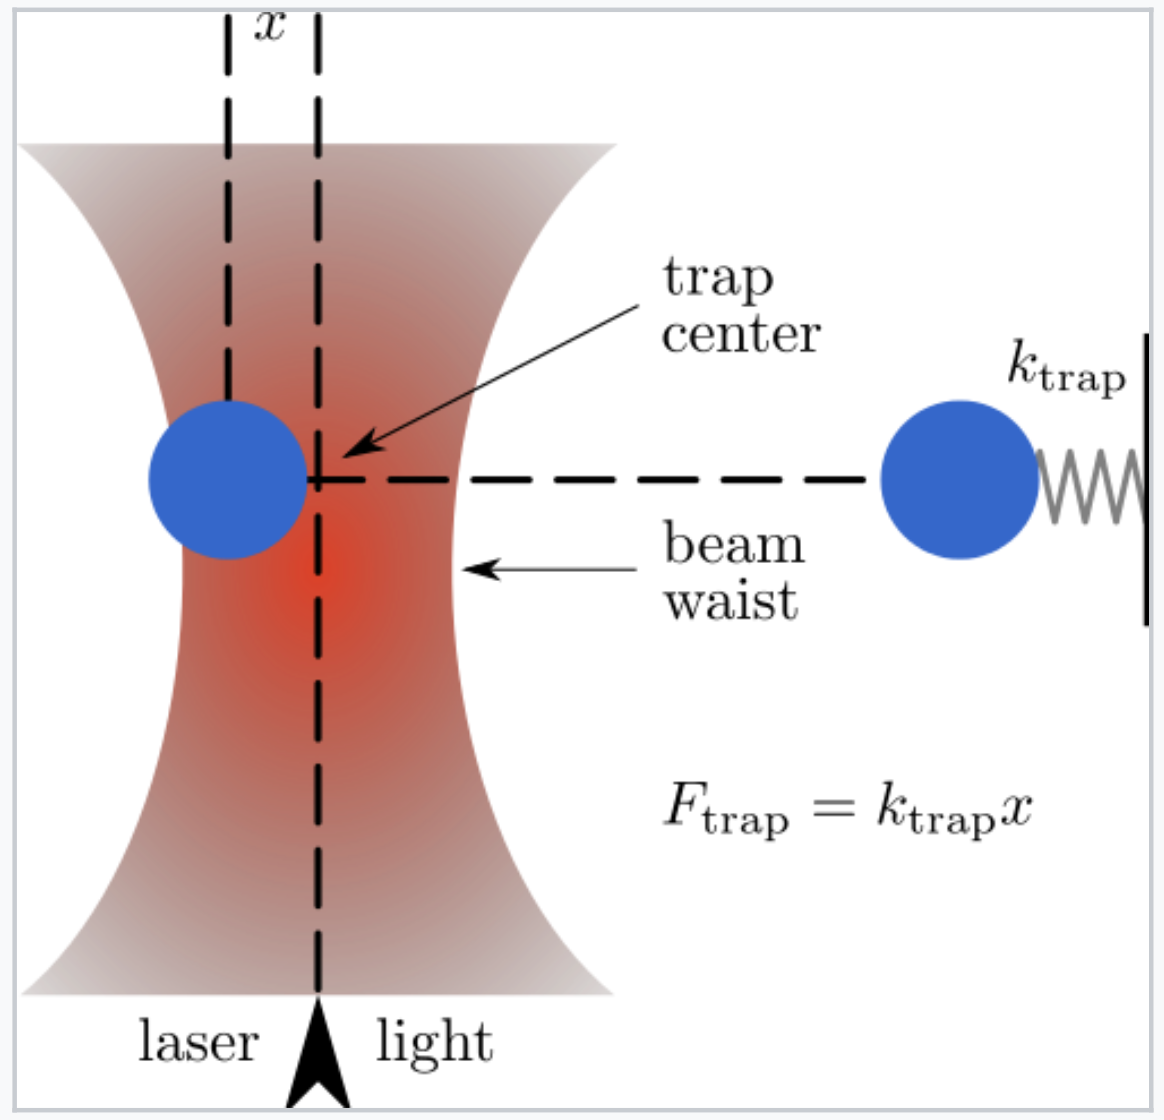 

                                                                               Image from https://en.wikipedia.org/wiki/Optical_tweezers